# Example 1.4: Pdf and Cdf of a Continuous RV

Note: this script reproduces Example 1.4 (Section 1.2.2) of **Statistics for Chemical Engineers**: a continuous RV with the standard Gaussian pdf. Victor Z UW-Madison, 2019 pdf and cdf of a simple continuous RV

clc; clear all; close all hidden;

rng(1); % For reproducibility 
mu=0;
sigma=1;
color="black";
x=linspace(-5,5,1000);

figure(1)

## Pdf

Note: f(x) is a density: probabilities are areas under the curve. plot pdf

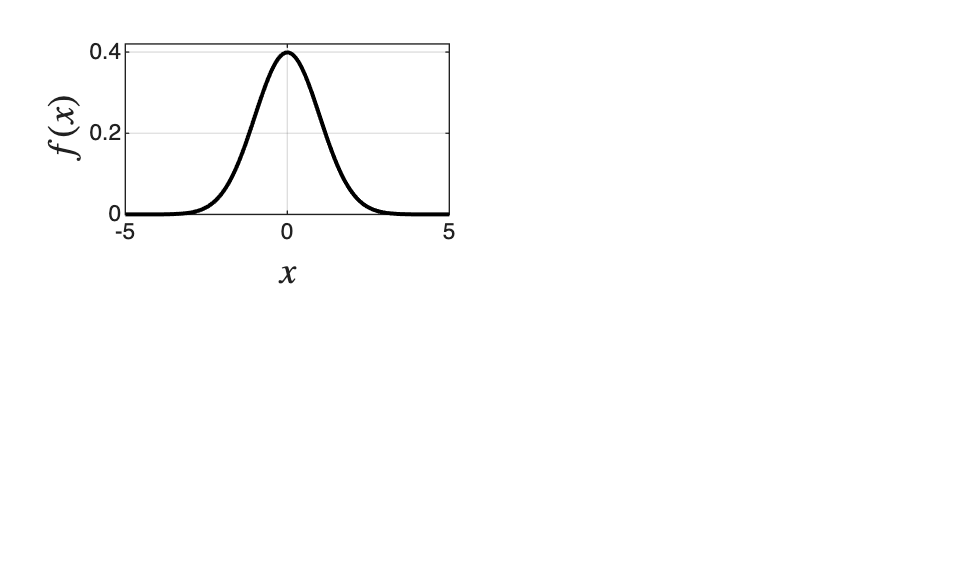

subplot(2,2,1)
plot(x,normpdf(x,mu,sigma),color,'LineWidth',1.5)
hold on
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')
axis([-5 5 0 0.42])

## Cdf

Note: F(x) is the area under the pdf up to x; it increases from 0 to 1. plot cdf

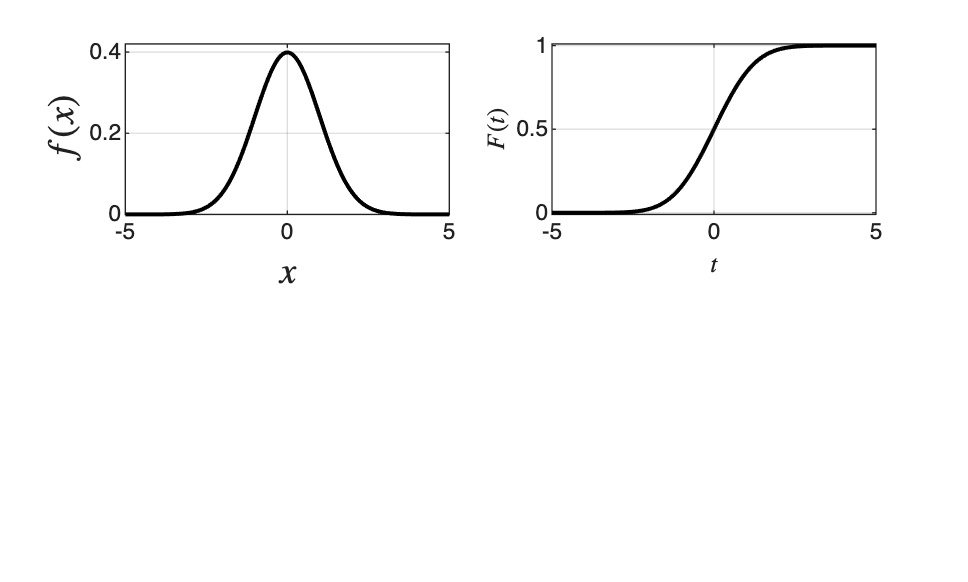

subplot(2,2,2)
for k=1:length(mu)
plot(x,normcdf(x,mu(k),sigma(k)),color(k),'LineWidth',1.5)
hold on
end
grid on
xlabel('$t$','Interpreter','latex')
ylabel('$F(t)$','Interpreter','latex')
title('')
axis([-5 5 -0.01 1.01])

## Discrete approximation of the pdf

Note: the probability of each bin divided by its width approximates the pdf. plot discrete approximation of pdf

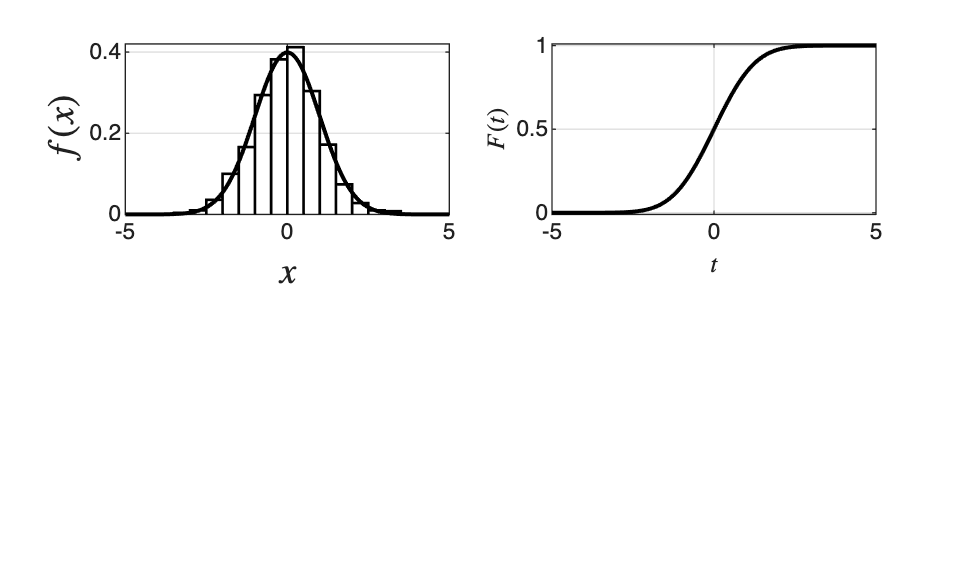

N=1000;
x = normrnd(0,1,N,1);
subplot(2,2,1)
histogram(x,'BinWidth',1/2,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
xlabel('$x$ [bar]','Interpreter','latex')
ylabel('$S\times {P}(X=x)$','Interpreter','latex')
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
axis([-5 5 0 0.42])


t=-5:0.5:5;
for i=1:length(t)
    F(i)=0;
    for j=1:length(x)
        F(i)=F(i)+(x(j)<=t(i))*(1/N);
    end
end

## Discrete approximation of the cdf

plot discrete approximation of cdf

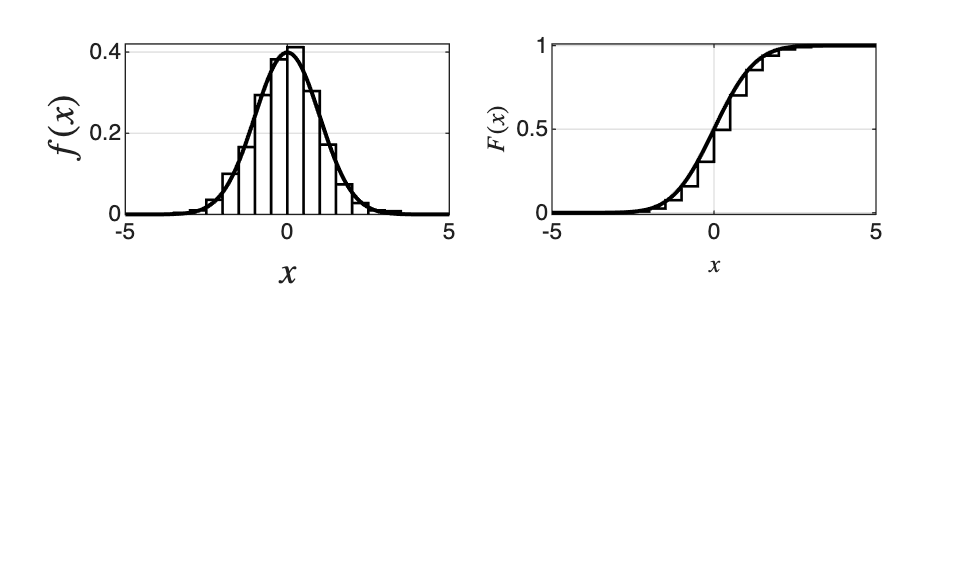

subplot(2,2,2)
stairs(t,F,'LineWidth',1,'Color','black')
xlabel('$x$','Interpreter','latex')
ylabel('$F(x)$','Interpreter','latex')
grid on
title('')
axis([-5 5 -0.01 1.01])

print -depsc ch1_pdfcdfcontinuous.eps

## Note

As in the book, the discretized pdf approximates the continuous one well: for bins of width 0.5, its peak is 0.38, close to f(0) = 0.4.